# iPhone LiDARで取得した3次元点群を地図上にプロットしてみよう

この記事は、MATLABアドベントカレンダーxx日目の記事として書かれています。

この記事では、iPhone LiDARで取得した3次元点群をMATLABにて読み込み、さらに、地図（地球）上で可視化する方法について紹介します。

3次元点群を取得するためのアプリはScaniverseを用いました。詳しい使い方は、以下の記事がわかりやすかったです。ここでは、すでにiPad LiDARにて計測し、PCに転送した状態から始めます。

なお、ここで用いたコードや、点群ファイルは以下のページにアップロードされています。

＜GITHUB＞

## 点群ファイルの読み込み

LiDAR toolboxの機能を用いて、点群データの読み込みを行います。以下のように、`lasFileReader`や`readPointCloud`関数を用いて、簡単に読み込むことができます。

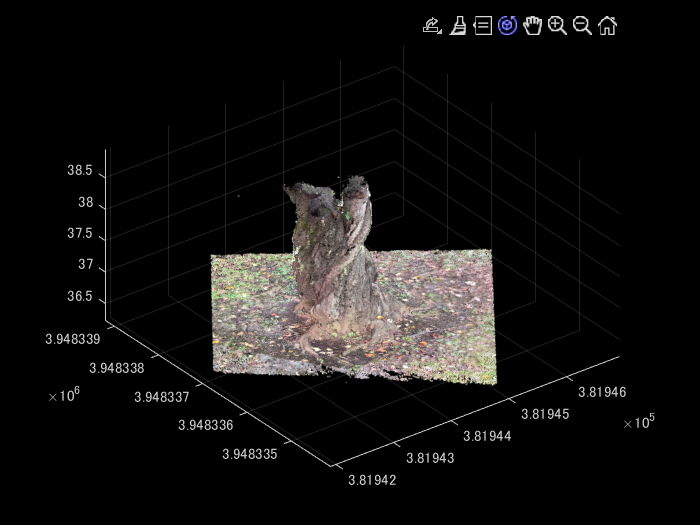

% las/lazファイルを読み込むためのlasFileReader objectを作成する
lasReader = lasFileReader('treeTrunk.laz');
% las/lazファイルの、xyzおよび色情報を読み込み
ptCloud = readPointCloud(lasReader);
% 可視化
figure('Visible','on');pcshow(ptCloud)

以下のように、複雑な3次元形状を有する、樹木の幹部分をきれいに点群化できていることがわかります。

## 座標系の変換

Scaniverseで、点群を取得し、エキスポートする場合、経度・緯度ではなく、2次元平面に投影した方式でxy座標が保存されます。

より詳しく述べると、UTM N54（EPSGコード：32654）でエキスポートされるので、これを経度・緯度に変換します。

projcrs関数に、EPSGコードを入力します。その結果、projcrsオブジェクトを作成することができます。

utm54N = projcrs(32654);
utm54N.GeographicCRS.Name

ans = "WGS 84"

projcrsオブジェクトの中身は以下のようになっています。

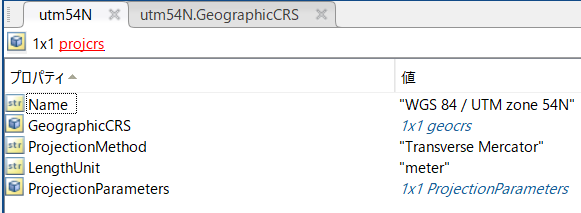

さらに、その中の、utm54N.GeographicCRSは、geocrsオブジェクトであり、その中身は以下のようになっています。

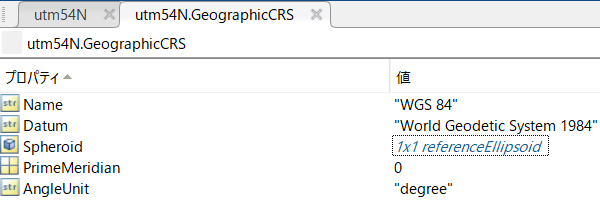

`projinv`関数を用いて、utm54Nのxy座標を経度・緯度に変換することができます。

この結果の可視化は、geoplot関数で行います。

すると、以下のように、地図の上に、さきほどの樹木の幹の点群をプロットすることができます。位置に関しても、この点群が取得された、東京都の代々木公園に正しくプロットされています。

ベースマップ（地図の種類）を変更するために、以下のように、geobasemapの中身を他のベースマップの種類を指定することもできます。

`geobasemap('topographic')`

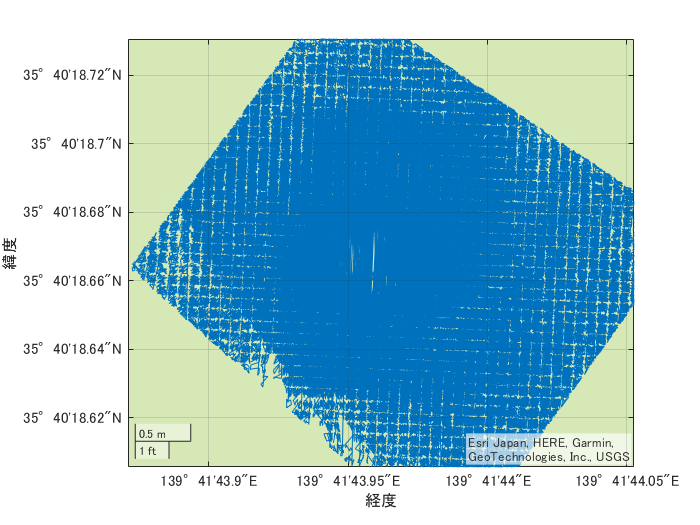

[lat,lon] = projinv(utm54N,ptCloud.Location(:,1),ptCloud.Location(:,2));
figure; geoplot(lat,lon)
% hold on;geobasemap('streets')
hold on;geobasemap('topographic')

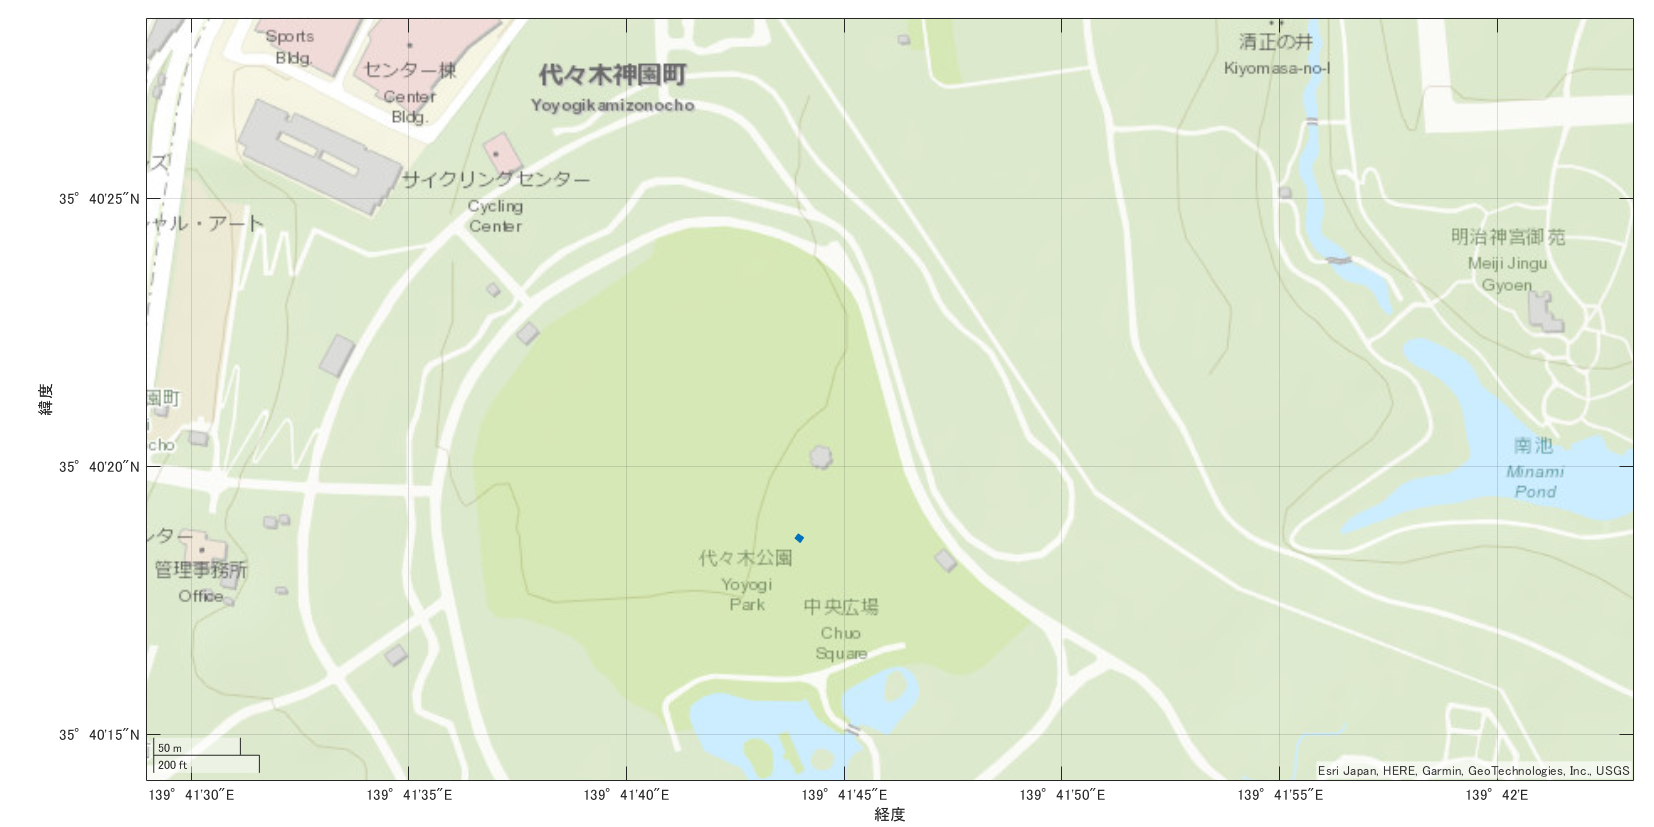

aaa

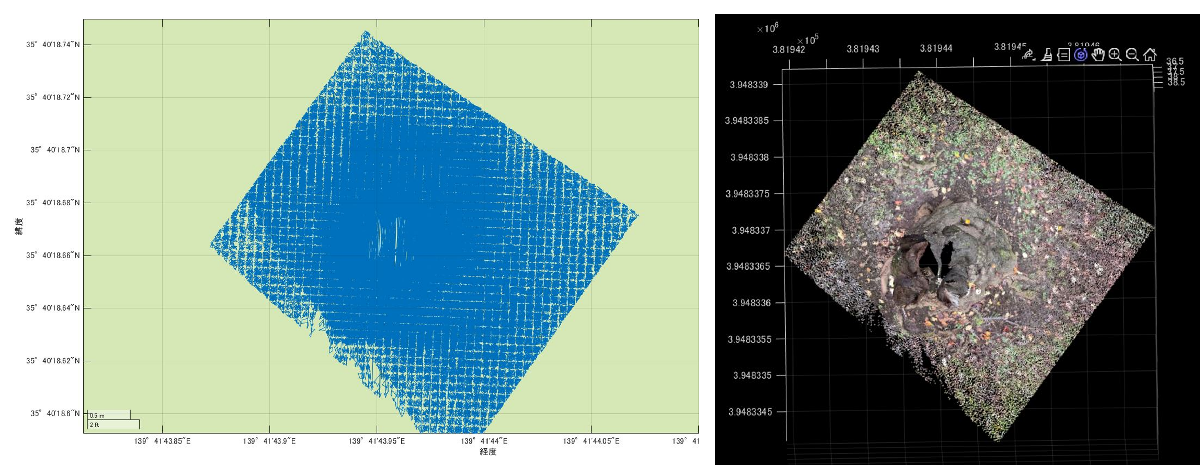

## 3次元マップでの点群の可視化

さきほどは、地図上にて、点群を可視化しましたが、2次元のマップであったため、各点の位置を知るということに限定されていました。このセクションでは、iPhone LiDARで取得した点群を、3次元のマップ上で可視化してみます。

mskip = 1:25:length(lat);

uif = uifigure;
g = geoglobe(uif);
geoplot3(g,lat,lon,ptCloud.Location(:,3)-mean(ptCloud.Location(:,3)),'r','MarkerSize',2,'Marker','o','HeightReference','terrain','LineStyle','none','MarkerIndices',mskip)

## まとめ

- この記事では、iPhone LiDARで取得した点群をMATLABを用いて、地図上で可視化しました

## 参考にしたページ

https://jp.mathworks.com/help/map/transform-coordinates-to-different-pcrs.html